#  Homework 5: RRR elbow type Robot

**Mostafa Osama Ahmed**

**Innopolis University - DoNRS course**

Github Link: 

[https://github.com/mostafa-metwaly/DoNRs-HW5](https://github.com/mostafa-metwaly/DoNRs-HW5)

## Forward Kinematics


$$H=R_z \left(\textrm{q1}\right)\cdot T_z \left(\textrm{L1}\right)\cdot R_y \left(\textrm{q2}\right)\cdot T_x \left(\textrm{L2}\right)\cdot R_y \left(\textrm{q3}\right)\cdot T_x \left(\textrm{L3}\right)$$


clear all
close all

% set angles as symbolical
syms q1 q2 q3   real
%Link lengths
L1=1

L1 = 1

L2=1

L2 = 1

L3=1

L3 = 1

L=[L1, L2 L3];
% FK symbolical
FK=simplify(Rz(q1)*Tz(L1)*Ry(q2)*Tx(L2)*Ry(q3)*Tx(L3))

$$FK = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{1}\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{2}+q_{3}\right) & 0 & \cos\left(q_{2}+q_{3}\right) & 1-\sin\left(q_{2}\right)-\sin\left(q_{2}+q_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$




q=[0.7854 -0.7854 1.3708 ]

q =     0.7854   -0.7854    1.3708


 FK= (Rz(q(1))*Tz(L1)*Ry(q(2))*Tx(L2)*Ry(q(3))*Tx(L3))

FK =     0.5894   -0.7071    0.3907    1.0894
    0.5894    0.7071    0.3907    1.0894
   -0.5525         0    0.8335    1.1546
         0         0         0    1.0000


T=FK(1:3,4);
px=T(1)

px = 1.0894

py=T(2)

py = 1.0894

pz=T(3)

pz = 1.1546

## Inverse Kinematics

 q=InverseKinematics(FK)

q =    -0.8760   -0.4014    1.9722
    0.8760   -0.4014    1.9722
    3.1416   -0.9854    2.5562
         0    0.5236    2.0944


## **Jacobian**

### **Numerical derivatives**

syms q1 q2 q3   real
 % forward kinematics
H = Rz(q1)*Tz(L1)*Ry(q2)*Tx(L2)*Ry(q3)*Tx(L3);
H=simplify(H);
% extract rotation matrix
R = simplify(H(1:3,1:3));
% diff by q1
Td=Rzd(q1)*Tz(L1)*Ry(q2)*Tx(L2)*Ry(q3)*Tx(L3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 1st column
J1 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\sigma_{3}\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\sigma_{4}-\sigma_{2}\\ 0\\ 0\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}+\sigma_{6}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{1}-\sigma_{3}\right)}{\sigma_{7}+\sigma_{6}}\\ \frac{{\sin\left(q_{1}\right)}^{2}}{{\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2}}+\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{4}-\sigma_{2}\right)}{\sigma_{5}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{5}=\sigma_{7}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{7}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{6}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{6}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{6}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{7}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$

% diff by q2
Td=Rz(q1)*Tz(L1)*Ryd(q2)*Tx(L2)*Ry(q3)*Tx(L3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J2 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J2 = \begin{array}{l} \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{4}-\sigma_{3}\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-\sigma_{2}-\sigma_{1}\\ \sigma_{5}-\sigma_{6}-\cos\left(q_{2}\right)\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\sigma_{6}-\sigma_{5}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}}\\ \frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{\sigma_{9}+\sigma_{8}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{4}+\sigma_{3}\right)}{\sigma_{9}+\sigma_{8}}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{2}+\sigma_{1}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{7}=\sigma_{9}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{9}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{8}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{8}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{8}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{9}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$

% diff by q3
Td=Rz(q1)*Tz(L1)*Ry(q2)*Tx(L2)*Ryd(q3)*Tx(L3)*...
    [R^-1 zeros(3,1);0 0 0 1];
% extract 6 components from 4x4 Td matrix to Jacobian 2nd column
J3 = [Td(1,4), Td(2,4), Td(3,4), Td(3,2), Td(1,3), Td(2,1)]' 

$$J3 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{4}-\sigma_{3}\\ -\sigma_{2}-\sigma_{1}\\ \sigma_{5}-\sigma_{6}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\sigma_{6}-\sigma_{5}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\right)}{\sigma_{7}}\\ \frac{\cos\left(q_{2}+q_{3}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)}{\sigma_{9}+\sigma_{8}}+\frac{\sin\left(q_{2}+q_{3}\right)\,\left(\sigma_{4}+\sigma_{3}\right)}{\sigma_{9}+\sigma_{8}}\\ -\frac{\cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sigma_{2}+\sigma_{1}\right)}{\sigma_{7}}-\frac{\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\,\left(\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)-\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\right)}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)\\ \sigma_{3}=\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{5}=\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sigma_{6}=\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\\ \sigma_{7}=\sigma_{9}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{9}\,{\sin\left(q_{1}\right)}^{2}+\sigma_{8}\,{\cos\left(q_{1}\right)}^{2}+\sigma_{8}\,{\sin\left(q_{1}\right)}^{2}\\ \sigma_{8}={\sin\left(q_{2}+q_{3}\right)}^{2}\\ \sigma_{9}={\cos\left(q_{2}+q_{3}\right)}^{2} \end{array}$$

 
% Full Jacobian 3x3
Jq = [simplify(J1), simplify(J2), simplify(J3)]

$$Jq = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{2} & -\cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{2} & -\sin\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}+q_{3}\right)-\cos\left(q_{2}\right) & -\cos\left(q_{2}+q_{3}\right)\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\\ 1 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right)\\ \sigma_{2}=\cos\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right) \end{array}$$

## Trajectory

### Task 1

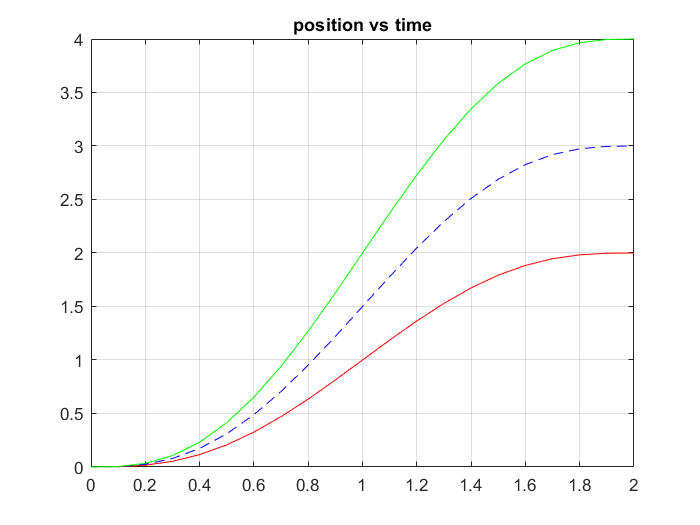

% Q2
% define the initial and final conditions
 

t0 = 0; tf = 2;
q0 = [0 0 0]; qf = [2 3 4]; 
v0 = 0; vf = 0;
acc0 = 0; accf = 0;
tf = 2;
q_all=zeros(21,3);
v_all= zeros(21,3);
acc_all=zeros(21,3); 

for i=1:3
%Given:
A = [1 t0 t0^2 t0^3 t0^4 t0^5
     0 1 2*t0 3*t0^2 4*t0^3 5*t0^4
     0 0 2 6*t0 12*t0^2 20*t0^3
     1 tf tf^2 tf^3 tf^4 tf^5
     0 1 2*tf 3*tf^2 4*tf^3 5*tf^4
     0 0 2 6*tf 12*tf^2 20*tf^3];
c = [q0(i);v0;acc0;qf(i);vf;accf];
b = A\c;
% assign the results to the coefficients 
a0 = b(1); a1 = b(2); a2 = b(3); a3 = b(4); a4 = b(5); a5 = b(6);


t = 0:0.1:2;
q = a0+a1.*t+a2.*t.^2+a3.*t.^3+a4.*t.^4+a5.*t.^5;
v = a1+2*a2.*t+3*a3.*t.^2+4*a4.*t.^3+5*a5.*t.^4;
acc = 2*a2+6*a3.*t+12*a4.*t.^2+20*a5.*t.^3;

q_all(:,i) = q;
v_all(:,i) = v;
acc_all(:,i)  = acc ;
end

figure
plot(t,q_all(:,1),'r-',t,q_all(:,2),'b--',t,q_all(:,3),'g-')
title('position vs time')
grid on

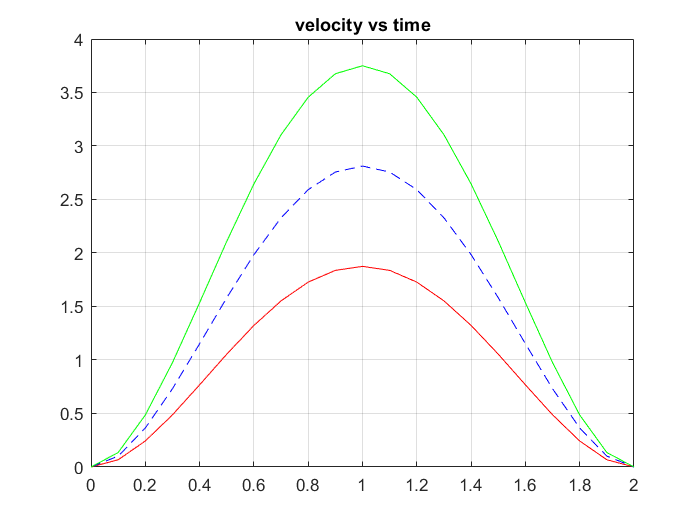

figure
plot(t,v_all(:,1),'r-',t,v_all(:,2),'b--',t,v_all(:,3),'g-')
title('velocity vs time')
grid on

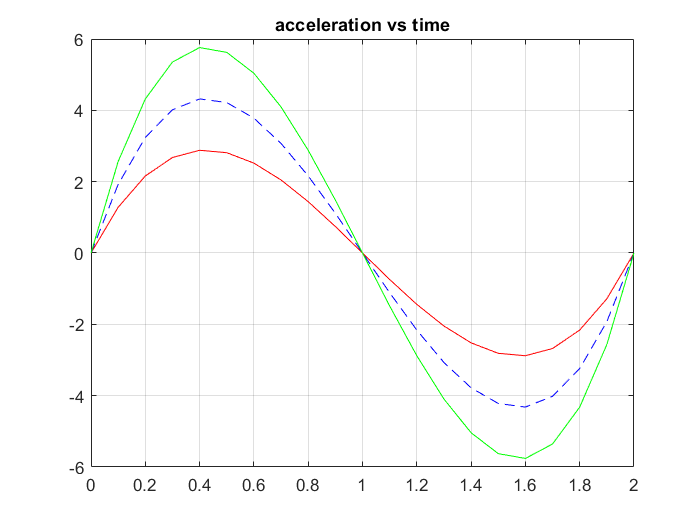

figure
plot(t,acc_all(:,1),'r-',t,acc_all(:,2),'b--',t,acc_all(:,3),'g-')
title('acceleration vs time')
grid on

### Task 2

`Calculate Joint Trajectory (Trapezoidal) for PTP Given`

`q(t) from q(0) = (0, 0, 0) to q(2) = (2, 3, 4)`

`Controller command interpretation frequency f = 100 Hz`

`Maximum joint velocity = 1 rad/s`

`Maximum joint acceleration = 10 rad/s2`


$$q\left(t\right)=\left\lbrace \begin{array}{cc}
a_{10} +a_{11} t+a_{12} t^2  & 0\le t\le t_a \\
a_{20} +a_{21} t & t_a <t<t_f -t_a \\
a_{30} +a_{31} t+a_{32} t^2  & t_f -t_a <t<t_f 
\end{array}\right.$$


where $t_a$ and $t_f -t_a$ is the period when the joint moves in constant velocity and they computed as follows:


$$t_a =\frac{v_{\max } }{a_{\max } }$$



$$t_f =\frac{q_f -q_0 }{v_{\max } }+t_a$$


 
clear all 
close all;clc;
q0 = [0 0 0]; qf = [2 3 4]; v_max = [1 1 1]; a_max = [10 10 10];
v0= [0 0 0];
dt = 0.01;
n = 0;

while (floor(dt*10^n)~=dt*10^n)
    n=n+1;
end
E = 1*10^-n;
ta = v_max./a_max;

delta_q = (qf(:)-q0(:));
tf = (delta_q(:))./v_max + ta;
taw=delta_q ./v_max;

if rem(ta,dt)~=0
    ta_new = round(ta,n)+E;
else
    ta_new = round(ta,n);
end
 tf = (qf(:)-q0(:))./v_max(:)  + ta_new(:);

if rem(tf,dt)~=0
    tf_new = round(tf,n)+E;
else
    tf_new = round(tf,n);
end

ta_new=max(ta_new)

ta_new = 0.1000

tf_new=max(tf_new)

tf_new = 4.1000


v_old =((qf(:)-q0(:))./(tf-ta));
a_old = v_old/ta;

v = ((qf(:)-q0(:))./(tf_new-ta_new))

v =     0.5000
    0.7500
    1.0000


a = v/ta_new

a =     5.0000
    7.5000
   10.0000




% all joints - coefficients:
for i =1:3

% t0 --> ta:
a10 = q0(i);
a11 = v0(i);
a12 = 0.5*a(i);

% ta --> tf-ta:
a20 = q0(i) + 0.5*a(i)*ta_new^2 - v(i)*ta_new;
a21 = v(i);

% tf-ta --> tf:
a30 = qf(i) - 0.5*a(i)*tf_new^2;
a31 = a(i)*tf_new;
a32 = -0.5*a(i);

 b(i,:) = [a10; a11; a12; a20; a21; a30; a31; a32];
end

t = 0:dt:tf_new;
v=zeros(3,length(t)); 
for i=1:3
    
q(i,:) = (b(i,1)+b(i,2).*t+b(i,3).*t.^2).*(t<=ta_new)...
    +(b(i,4)+b(i,5).*t).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(b(i,6)+b(i,7).*t+b(i,8).*t.^2).*(t>(tf_new-ta_new)).*(t<=tf_new);

v(i,:) = (b(i,2)+2*b(i,3).*t).*(t<=ta_new)...
    +(b(i,5)).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(b(i,7)+2*b(i,8).*t).*(t>(tf_new-ta_new)).*(t<=tf_new);

acc(i,:) = (2*b(i,3)).*(t<=ta_new)...
    +(0).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(2*b(i,8)).*(t>(tf_new-ta_new)).*(t<=tf_new);

end


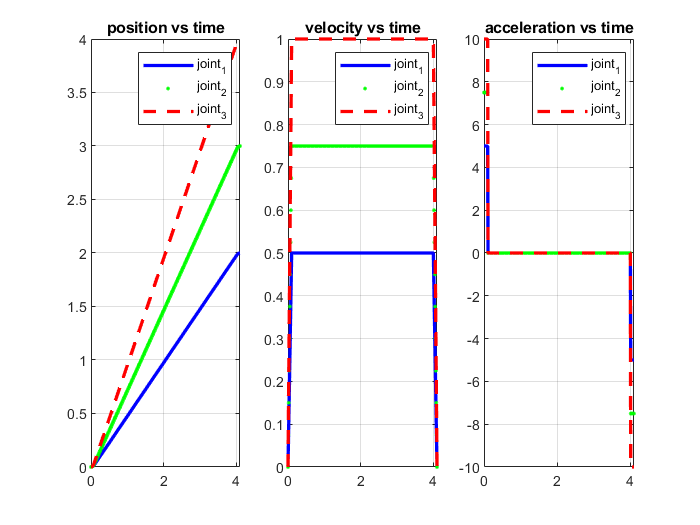


figure
subplot(1,3,1)
plot(t,q(1,:),'b-','linewidth',2)
hold on
plot(t,q(2,:),'g.','linewidth',2)
hold on
plot(t,q(3,:),'r--','linewidth',2)
grid on
title('position vs time')
legend('joint_1','joint_2','joint_3')
axis([0 tf_new -inf inf])

subplot(1,3,2)
plot(t,v(1,:),'b-','linewidth',2)
hold on
plot(t,v(2,:),'g.','linewidth',2)
hold on
plot(t,v(3,:),'r--','linewidth',2)
title('velocity vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

subplot(1,3,3)
plot(t,acc(1,:),'b-','linewidth',2)
hold on
plot(t,acc(2,:),'g.','linewidth',2)
hold on
plot(t,acc(3,:),'r--','linewidth',2)
title('acceleration vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

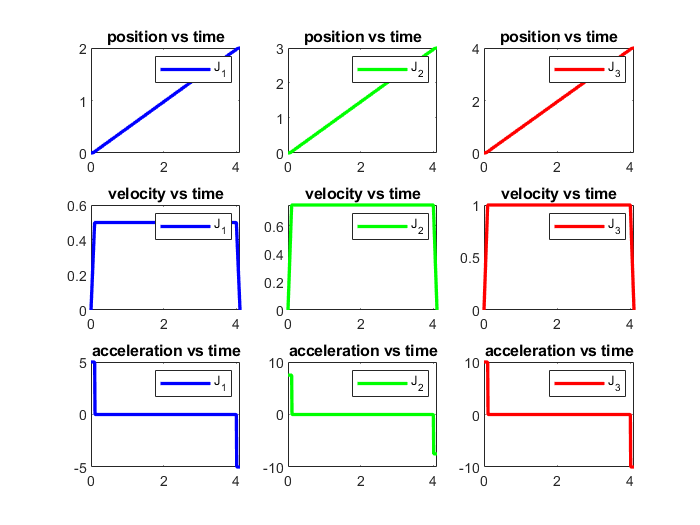


figure;
subplot(3,3,1);plot(t,q(1,:),'b-','linewidth',2);title('position vs time');legend('J_1');
subplot(3,3,2);plot(t,q(2,:),'g-','linewidth',2);title('position vs time');legend('J_2');
subplot(3,3,3);plot(t,q(3,:),'r-','linewidth',2 );title('position vs time');legend('J_3');

subplot(3,3,4);plot(t,v(1,:),'b-','linewidth',2);title('velocity vs time');legend('J_1');
subplot(3,3,5);plot(t,v(2,:),'g-','linewidth',2);title('velocity vs time');legend('J_2');
subplot(3,3,6);plot(t,v(3,:),'r-','linewidth',2 );title('velocity vs time');legend('J_3');

subplot(3,3,7);plot(t,acc(1,:),'b-','linewidth',2);title('acceleration vs time');legend('J_1');
subplot(3,3,8);plot(t,acc(2,:),'g-','linewidth',2);title('acceleration vs time');legend('J_2');
subplot(3,3,9);plot(t,acc(3,:),'r-','linewidth',2 );title('acceleration vs time');legend('J_3');
hold off

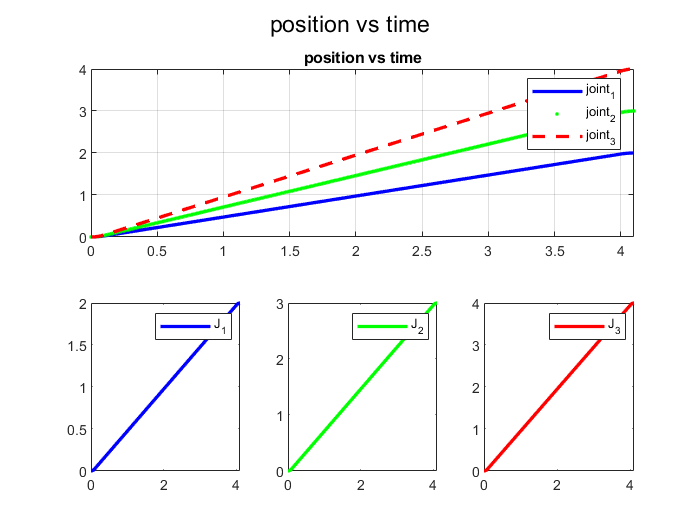


figure
subplot(2,3,1:3)
plot(t,q(1,:),'b-','linewidth',2)
hold on
plot(t,q(2,:),'g.','linewidth',2)
hold on
plot(t,q(3,:),'r--','linewidth',2)
grid on
title('position vs time')
legend('joint_1','joint_2','joint_3')
axis([0 tf_new -inf inf])

subplot(2,3,4);plot(t,q(1,:),'b-','linewidth',2);sgtitle('position vs time');legend('J_1');
subplot(2,3,5);plot(t,q(2,:),'g-','linewidth',2);sgtitle('position vs time');legend('J_2');
subplot(2,3,6);plot(t,q(3,:),'r-','linewidth',2 );sgtitle('position vs time');legend('J_3');

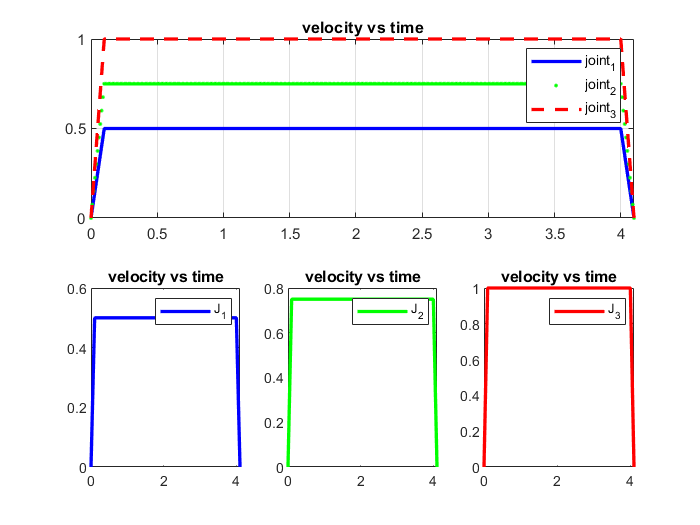



figure;
subplot(2,3,1:3)
plot(t,v(1,:),'b-','linewidth',2)
hold on
plot(t,v(2,:),'g.','linewidth',2)
hold on
plot(t,v(3,:),'r--','linewidth',2)
title('velocity vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

subplot(2,3,4);plot(t,v(1,:),'b-','linewidth',2);title('velocity vs time');legend('J_1');
subplot(2,3,5);plot(t,v(2,:),'g-','linewidth',2);title('velocity vs time');legend('J_2');
subplot(2,3,6);plot(t,v(3,:),'r-','linewidth',2 );title('velocity vs time');legend('J_3');

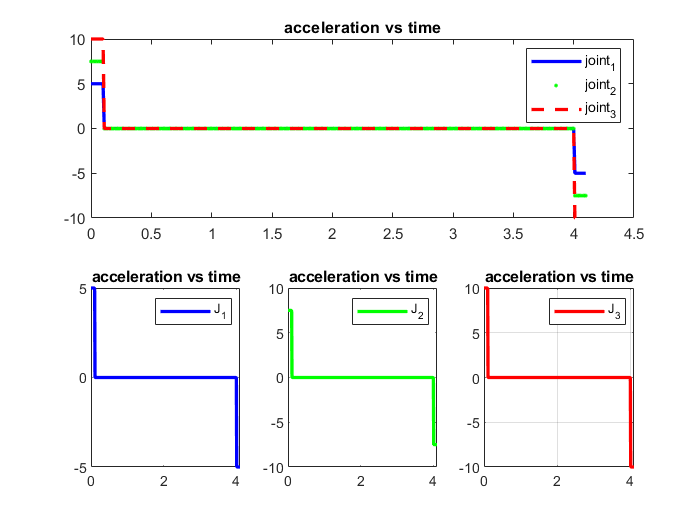


figure;
subplot(2,3,1:3)
plot(t,acc(1,:),'b-','linewidth',2)
hold on
plot(t,acc(2,:),'g.','linewidth',2)
hold on
plot(t,acc(3,:),'r--','linewidth',2)
title('acceleration vs time')
legend('joint_1','joint_2','joint_3')

subplot(2,3,4);plot(t,acc(1,:),'b-','linewidth',2);title('acceleration vs time');legend('J_1');
subplot(2,3,5);plot(t,acc(2,:),'g-','linewidth',2);title('acceleration vs time');legend('J_2');
subplot(2,3,6);plot(t,acc(3,:),'r-','linewidth',2 );title('acceleration vs time');legend('J_3');
grid on
axis([0 tf_new -inf inf])

### **Task 3**

Joint trajectory for the following commands: LIN – p1 = (1, 0, 1) to p2 = (√2/2, √2/2, 1.2) (trapezoidal)

-  Controller command interpretation frequency – f = 100 Hz

-  Maximum linear velocity – 1 m/s

-  Maximum linear acceleration – 10 m/s2

clear all;
p1 = [ 1, 0, 1];
p2 = [sqrt(2)/2 sqrt(2)/2 1.2];
v_max = [1 1 1]; a_max = [10 10 10];
v0= [0 0 0];
dt = 0.01;
n = 0; 
N = 100;
 
while (floor(dt*10^n)~=dt*10^n)
    n=n+1;
end

ta =     0.1000    0.1000    0.1000


E = 1*10^-n;
ta = v_max./a_max
delta_p = (p2(:)-p1(:));

we will calcualate for the controller frequancy and recalculate the time by using maximum time

if rem(ta,dt)~=0
    ta_new = round(ta,n)+E;
else
    ta_new = round(ta,n);
end

 tf = (delta_p(:))./v_max(:)  + ta_new(:);

if rem(tf,dt)~=0
    tf_new = round(tf,n)+E;
else
    tf_new = round(tf,n);
end


ta_new = 0.1000

tf_new = 0.8200

ta_new=max(ta_new)
tf_new=max(tf_new)
% v_old =((p2(:)-p1(:))./(tf-ta));
% a_old = v_old/ta;
% 
% v = ((p2(:)-p1(:))./(tf_new-ta_new))
% a = v/ta_new

t_lin = linspace(0,tf_new,N);

we will then calculate all the waypoints positions and velocities that would make the straight line path between the given points in cartesian coordinates

% positions
% x = ((p2(1)-p1(1))/tf_new).*t+p1(1);
% y = ((p2(2)-p1(2))/tf_new).*t+p1(2);
% z = ((p2(3)-p1(3))/tf_new).*t+p1(3);
    waypnts = [((p2(:)-p1(:))./tf_new).*t_lin+p1(:)]';
% velocities
% vx = ((p2(1)-p1(1))/tf_new);
% vy = ((p2(2)-p1(2))/tf_new);
% vz = ((p2(3)-p1(3))/tf_new);
    vel = ((p2(:)-p1(:))/tf_new);
m = -1; % 1 elbow up, -1 elbow down         

we then calculate these waypoints from the cartesian space to the joint space getting joint andles and velocities using robot inverse kinematiks and jacobian matrix

for i=1:N
    waypnt = waypnts(i,:);
    jointangles(i,:) = InverseKinematics(waypnt);
    if i == 1 || i==N
        jointVelocity(i,:) = [0 0 0];
    else
        J = Jacobian(jointangles(i,:));
        jointVelocity(i,:) =  (J\vel)';
    end
end

we calculate the position ,velocity and acceleration for each joint for each waypoint and store there values.

n = 15;
num=0;
Q = [];
Vel = [];
Acc = [];
acc =[];
vel =[];
for i=1:N-1
    t1 = t_lin(i); t2 = t_lin(i+1);
    A = [1 t1 t1^2 t1^3
        0 1 2*t1 3*t1^2
        1 t2 t2^2 t2^3
        0 1 2*t2 3*t2^2];
    for j = 1:3
         q1 = jointangles(i,j); 
         q2 = jointangles(i+1,j);
         v1 = jointVelocity(i,j); 
         v2 = jointVelocity(i+1,j);
         c = [q1;v1;q2;v2];
         b = A\c;
         t = linspace(t1,t2,n);
         q(j,:) = b(1)+b(2).*t+b(3).*t.^2+b(4).*t.^3;
         vel(j,:) = b(2)+2*b(3).*t+3*b(4).*t.^2;
         acc(j,:) = 2* b(3)+6* b(4).*t;
         
    end   
    Q = [Q q];
    Vel = [Vel vel];
    Acc = [Acc acc];
    
end 

we check our solution by getting the forward kinematics for the joints and calculate the path and its velocity and acceleration from the jacobian and visualize the robot motion 

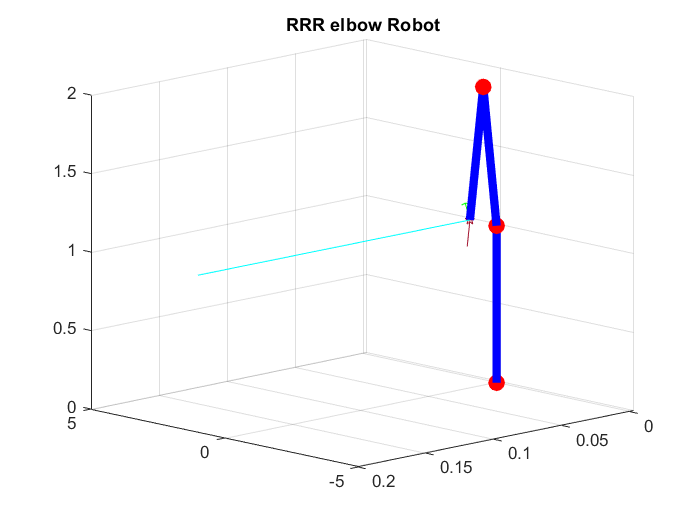

cartTrajectory = ForwardKinematics(Q'); 
for i=1:length(Q)
   jac= Jacobian(Q(:,i)');
   CartVelocity(:,i)= jac * Vel(:,i);
   CartAcceleration(i,:)= jac * Acc(:,i);
 

end
CartAcceleration=CartAcceleration';
cartTrajectory=cartTrajectory';
figure;

hold on

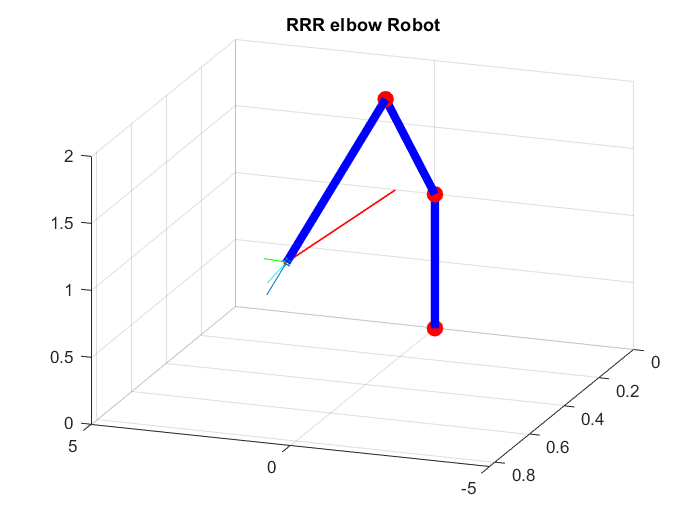

for i=1:50:length(Q)
   draw_myrobot([1 1 1],Q(:,i)')
   pause(0.01)
   cla
   plot3(waypnts(:,1),waypnts(:,2),waypnts(:,3),'r-','linewidth',1)

  end   
 draw_myrobot([1 1 1],Q(:,i)')
 num=n*N-n;
t  = linspace(0,tf_new,num);


these graphs draw the relation between all the joints position velocity and acceleration and also the linear position , velocity and acceleration of the end-effector motion.

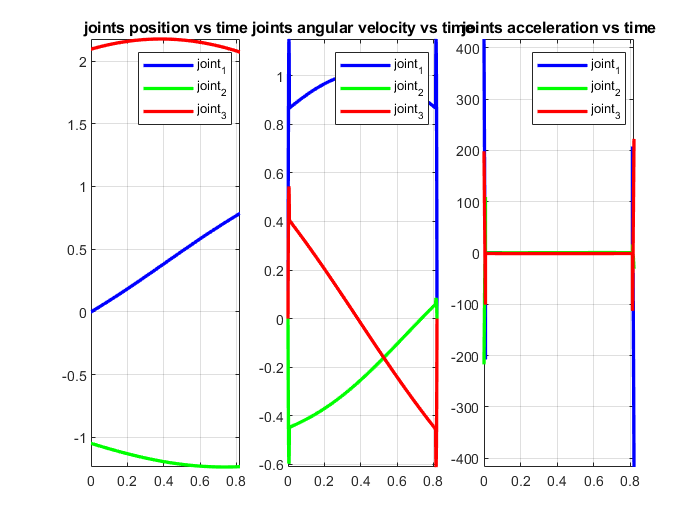

figure
subplot(1,3,1)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
plot(t,Q(2,:),'g-','linewidth',2)
hold on
plot(t,Q(3,:),'r-','linewidth',2)
grid on
title('joints position vs time')
legend('joint_1','joint_2','joint_3')
axis([0 tf_new -inf inf])

subplot(1,3,2)
plot(t,Vel(1,:),'b-','linewidth',2)
hold on
plot(t,Vel(2,:),'g-','linewidth',2)
hold on
plot(t,Vel(3,:),'r-','linewidth',2)
title('joints angular velocity vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

subplot(1,3,3)
plot(t,Acc(1,:),'b-','linewidth',2)
hold on
plot(t,Acc(2,:),'g-','linewidth',2)
hold on
plot(t,Acc(3,:),'r-','linewidth',2)
title('joints acceleration vs time')
legend('joint_1','joint_2','joint_3')

grid on
axis([0 tf_new -inf inf])

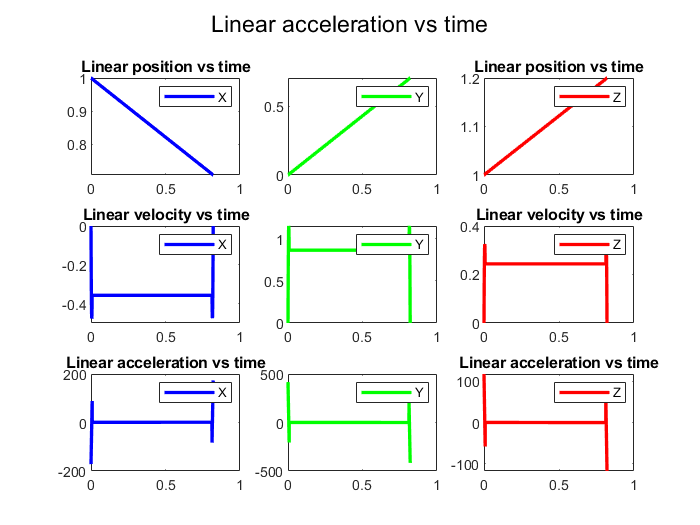


figure;
subplot(3,3,1);plot(t,cartTrajectory(1,:),'b-','linewidth',2);title('Linear position vs time');legend('X');
subplot(3,3,2);plot(t,cartTrajectory(2,:),'g-','linewidth',2);sgtitle('Linear position vs time');legend('Y');
subplot(3,3,3);plot(t,cartTrajectory(3,:),'r-','linewidth',2 );title('Linear position vs time');legend('Z');

subplot(3,3,4);plot(t,CartVelocity(1,:),'b-','linewidth',2);title('Linear velocity vs time');legend('X');
subplot(3,3,5);plot(t,CartVelocity(2,:),'g-','linewidth',2);sgtitle('Linear velocity vs time');legend('Y');
subplot(3,3,6);plot(t,CartVelocity(3,:),'r-','linewidth',2 );title('Linear velocity vs time');legend('Z');

subplot(3,3,7);plot(t,CartAcceleration(1,:),'b-','linewidth',2);title('Linear acceleration vs time');legend('X');
subplot(3,3,8);plot(t,CartAcceleration(2,:),'g-','linewidth',2);sgtitle('Linear acceleration vs time');legend('Y');

subplot(3,3,9);plot(t,CartAcceleration(3,:),'r-','linewidth',2 );title('Linear acceleration vs time');legend('Z');
hold off


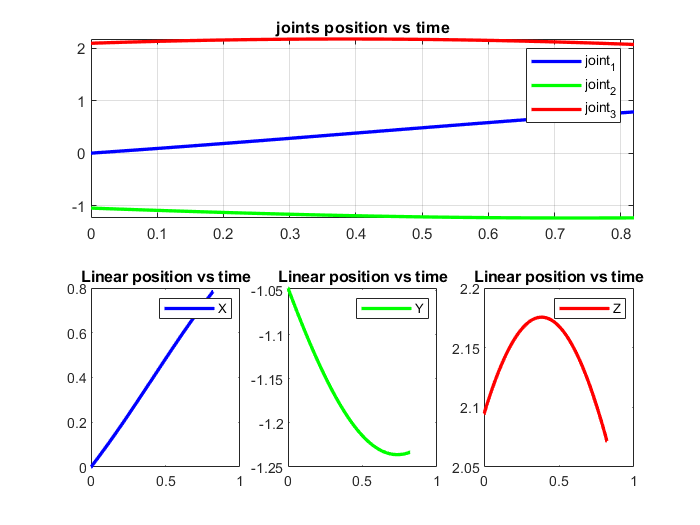


figure
subplot(2,3,1:3)
plot(t,Q(1,:),'b-','linewidth',2)
hold on
plot(t,Q(2,:),'g-','linewidth',2)
hold on
plot(t,Q(3,:),'r-','linewidth',2)
grid on
title('joints position vs time')
legend('joint_1','joint_2','joint_3')
axis([0 tf_new -inf inf])

subplot(2,3,4);plot(t,Q(1,:),'b-','linewidth',2);title('Linear position vs time');legend('X');

subplot(2,3,5);plot(t,Q(2,:),'g-','linewidth',2);title('Linear position vs time');legend('Y');
subplot(2,3,6);plot(t,Q(3,:),'r-','linewidth',2 );title('Linear position vs time');legend('Z');


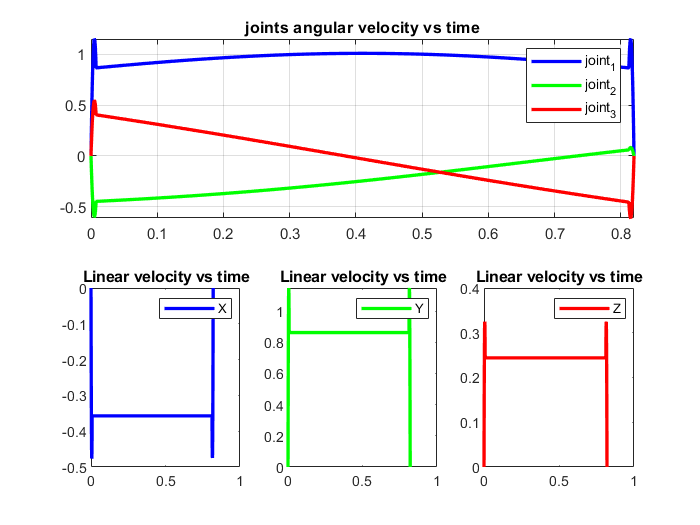


figure;
subplot(2,3,1:3)
plot(t,Vel(1,:),'b-','linewidth',2)
hold on
plot(t,Vel(2,:),'g-','linewidth',2)
hold on
plot(t,Vel(3,:),'r-','linewidth',2)
title('joints angular velocity vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

subplot(2,3,4);plot(t,CartVelocity(1,:),'b-','linewidth',2);title('Linear velocity vs time');legend('X');

subplot(2,3,5);plot(t,CartVelocity(2,:),'g-','linewidth',2);title('Linear velocity vs time');legend('Y');
subplot(2,3,6);plot(t,CartVelocity(3,:),'r-','linewidth',2 );title('Linear velocity vs time');legend('Z');

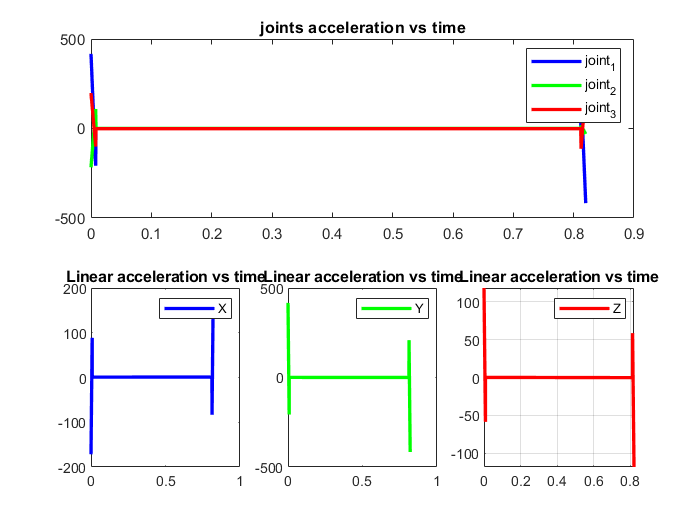


figure;
subplot(2,3,1:3)
plot(t,Acc(1,:),'b-','linewidth',2)
hold on
plot(t,Acc(2,:),'g-','linewidth',2)
hold on
plot(t,Acc(3,:),'r-','linewidth',2)
title('joints acceleration vs time')
legend('joint_1','joint_2','joint_3')

subplot(2,3,4);plot(t,CartAcceleration(1,:),'b-','linewidth',2);title('Linear acceleration vs time');legend('X');
subplot(2,3,5);plot(t,CartAcceleration(2,:),'g-','linewidth',2);title('Linear acceleration vs time');legend('Y');
subplot(2,3,6);plot(t,CartAcceleration(3,:),'r-','linewidth',2 );title('Linear acceleration vs time');legend('Z');

grid on
axis([0 tf_new -inf inf])